## MA 402 Project 1

### Friday March 11, 2022

### Andrea Stancescu, Jenna Varnell, Omry Bewster

% Andrea Stancescu, Jenna Varnell, Omry Brewster
% MA 402 Project 1 
% 3-11-2022
% MATLAB .mlx file with integrated text and code

### 1. Introduction

The purpose of this project is to model the Michaelis-Menten system which is a model of an enzyme reaction. The four components of the enzyme reaction are an enzyme (E), a substrate (S), the enzyme-substrate compound (C), and the product of the reaction (P). 

The Michaelis-Menten system is represented below as:

#### 
$$E+S\underset{\theta_1 }{\overset{\theta_2 }{\iff} } C\overset{\theta_3 }{\longrightarrow} E+P$$


Throughout the project, we will assume that the reaction rates are proportional to the product of the concentrations of the reactions which will lead us to the following system of four differential equations:

#### 
$$\begin{array}{l}
{\left\lbrack S\right\rbrack }^{\prime } \left(t\right)\;=-\theta_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack +\theta_2 \left\lbrack C\right\rbrack \\
{\left\lbrack E\right\rbrack }^{\prime } \left(t\right)=-\theta_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack +\left(\theta_2 +\theta_3 \right)\left\lbrack C\right\rbrack \\
{\left\lbrack C\right\rbrack }^{\prime } \left(t\right)={\;\theta }_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack -\left(\theta_2 +\theta_3 \right)\left\lbrack C\right\rbrack \\
{\left\lbrack P\right\rbrack }^{\prime } \left(t\right)=\theta_3 \left\lbrack C\right\rbrack \;\;
\end{array}$$


Throughout the project we will also use $\theta_1$ to signify the forward reaction rate coefficient, $\theta_2 \;$to signify the reverse reaction rate coefficient, and $\theta_3$ to represent the catalytic reaction rate coefficient. Furthermore, we will also use the following initial values when solving the system of equations using differential methods and Euler's method:

#### 
$$\begin{array}{l}
E_0 =5*{10}^{-2\;} \;\frac{\mathrm{mol}}{L}\\
S_0 =2*{10}^{-2} \;\frac{\mathrm{mol}}{L}\\
C_0 =0\;\frac{\mathrm{mol}}{L}\\
P_0 =0\;\frac{\mathrm{mol}}{L}
\end{array}$$


### 2 Differentiation Method 

The initial value problem is solved using differentiation and the ode45() function in MATLAB. 

#### 2.1 Results

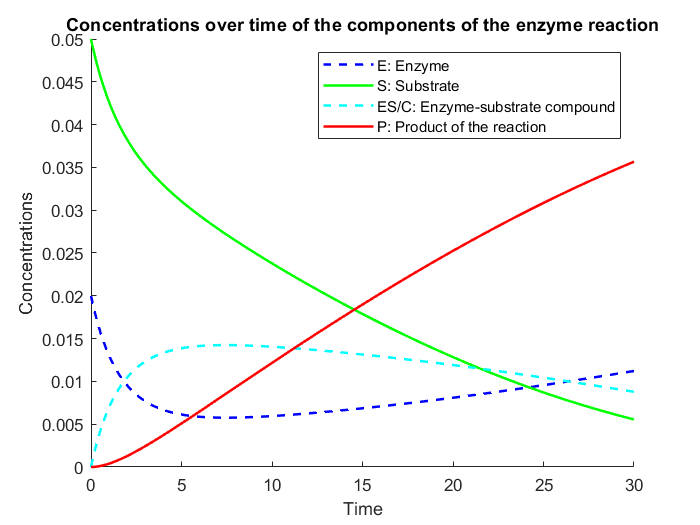


%% part a 

theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];


ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)];

[t, y] = ode45(ddt, [0 30], x0);

figure;
hold on 
plot(t, y(:,1), 'b--', 'LineWidth', 1.5)
plot(t, y(:,2), 'g', 'LineWidth', 1.5)
plot(t, y(:,3), 'c--', 'LineWidth', 1.5)
plot(t, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time of the components of the enzyme reaction')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

### 3. Euler's Method

#### 3.1 Results with a Step Size of 0.1

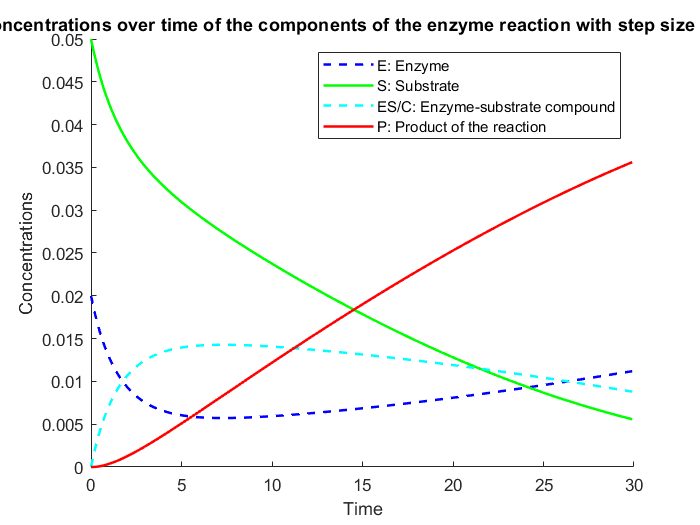


%% part b 
% step size h = 0.1
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h = 0.1;
y = zeros((30/h), 4);
y(1, :) = x0';
for i=1:((30/h) - 1)
   y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:)));
end

figure;
hold on 
plot(0:h:30-h, y(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,2), 'g', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time of the components of the enzyme reaction with step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

#### 3.2 Results with a Step Size of 1

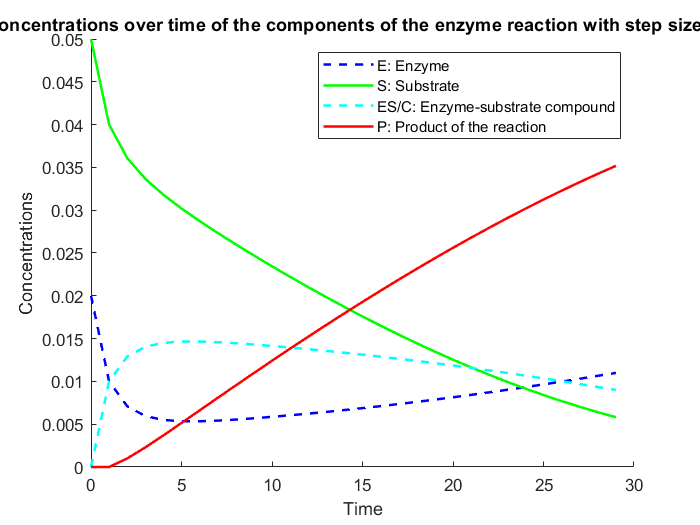

%% part b  
% step size h = 1
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h = 1;
y = zeros((30/h), 4);
y(1, :) = x0';
for i=1:((30/h) - 1)
   y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:)));
end

figure;
hold on 
plot(0:h:30-h, y(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,2), 'g', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time of the components of the enzyme reaction with step size of 1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

#### 3.3 Results with a Step Size of 2

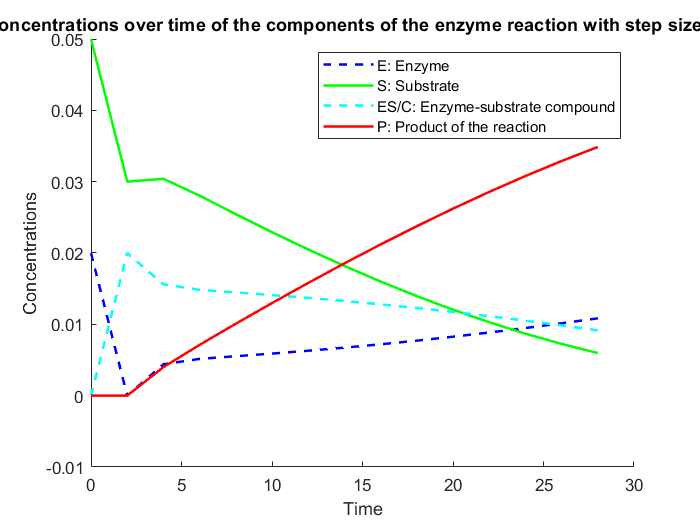

%% part b 
% step size h = 2

theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h = 2;
y = zeros((30/h), 4);
y(1, :) = x0';
for i=1:((30/h) - 1)
   y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:)));
end

figure;
hold on 
plot(0:h:30-h, y(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,2), 'g', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h:30-h, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time of the components of the enzyme reaction with step size of 2')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

### 4. Differentiation Method with Lognormal Reaction Rate Coefficients

#### 4.1 Results of 50 trials 

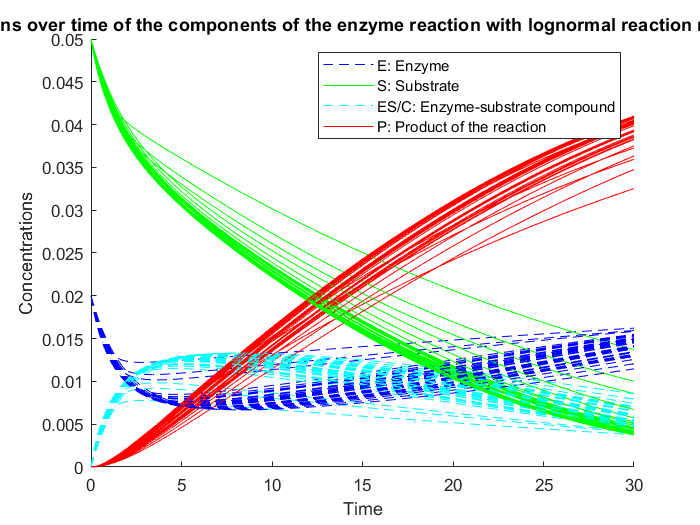


%% part c

e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    [t, y] = ode45(ddt, [0 30], x0);

    plot(t, y(:,1), 'b--')
    plot(t, y(:,2), 'g')
    plot(t, y(:,3), 'c--')
    plot(t, y(:,4), 'r')
end 

title('Concentrations over time of the components of the enzyme reaction with lognormal reaction rate coefficients')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### 4.2 Estimated Final Product Concentration 



%% part d

e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    [t, y] = ode45(ddt, [0 30], x0);

    lastproduct(i) = y(end,4);
end 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0007 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0007 , 0.0022] 


### 5. Euler's Method with Lognormal Reaction Rate Coefficients 

#### 5.1 Results with a Step Size of 2

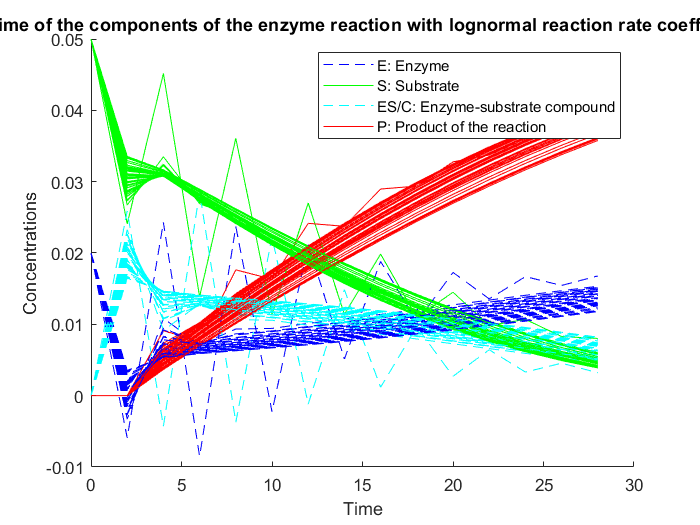

%% part e

% step size h = 2
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 2;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(i) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time of the components of the enzyme reaction with lognormal reaction rate coefficients and step size of 2')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0008 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0008 , 0.0024] 


#### 5.2 Results with a Step Size of 1

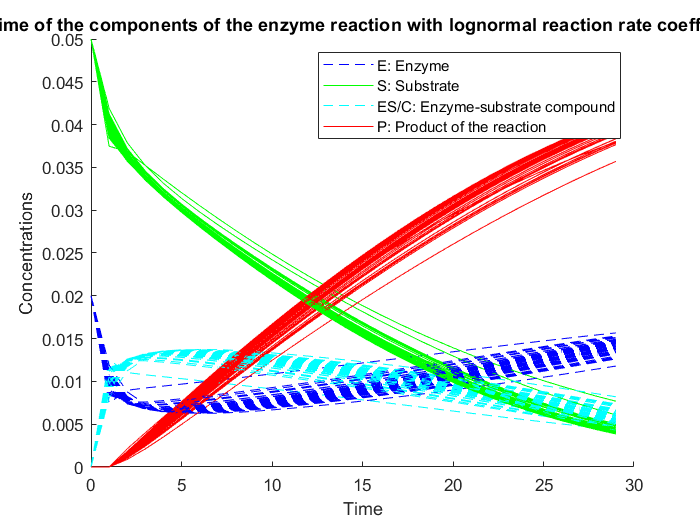

%% part e

% step size h = 1
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 1;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(i) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time of the components of the enzyme reaction with lognormal reaction rate coefficients and step size of 1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0008 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0008 , 0.0024] 


#### 5.2 Results with a Step Size of 0.1

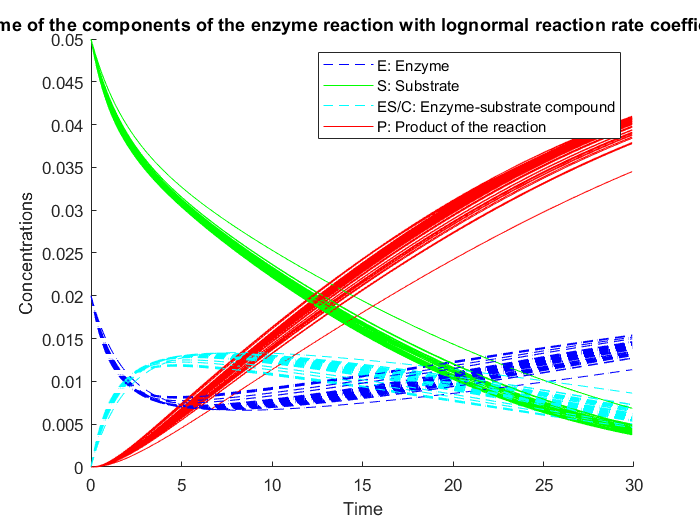

%% part e

% step size h = 0.1
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.09*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.09*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 0.1;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(i) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time of the components of the enzyme reaction with lognormal reaction rate coefficients and step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0001 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [-0.0005 , 0.0008] 
